% Initialisierung der Zustandsvariablen
R_0 = [0; 0; 0];  % Anfangsposition (Nullvektor)
V_0 = [0; 0; 0];  % Anfangsgeschwindigkeit (Nullvektor)

% Zeitbereich auf eine Minute erweitern
t = linspace(0, 120, 240);

% Beschleunigung in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
A = [1 * cos(t/12); 0.5 * sin(t/12); 0.05 * ones(size(t/12))];

% Geschwindigkeit in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
V = cumtrapz(t/12, A, 2) + V_0;

% Position in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
R_pos = R_0 + cumtrapz(t/12, V, 2) + 0.5 * cumtrapz(t/12, A, 2) .* t;

% Anzahl der Zeitschritte
N = length(t);

% Radarpositionen
pos_radar1 = [0, -10, 0];
pos_radar2 = [-50, 30, 0];

% Zustandsvektor x_k (6-dimensional: [x, y, z, vx, vy, vz])
x_k = [R_pos(1,:); R_pos(2,:); R_pos(3,:); V(1,:); V(2,:); V(3,:)];



% Prozessrauschkovarianzmatrix Q (Annahme: Prozessrauschen ist 0, da wir noch keine weiteren Informationen haben)
Q = zeros(6);

% Messrauschkovarianzmatrix R (Annahme: gleiche Varianzen für alle Beobachtungen)
standardabweichung = 0.1;
R = (standardabweichung^2) * eye(6);

% Zustandsübergangsmatrix F (Identity matrix as we assume constant velocity)
% Zeitschrittgröße
dt = t(2) - t(1);

% Zustandsübergangsmatrix F
F = [eye(3), dt/12 * eye(3);
     zeros(3), eye(3)];
% Schätzung der Anfangsvarianz des Zustandsvektors (Annahme: großer Wert, da wir wenig über den Anfangszustand wissen)
P = 1000 * eye(6);

% EKF-Schätzung
for k = 2:N
    % Vorhersage
    x_k_pred = F * x_k(:, k-1);
    P_pred = F * P * F' + Q;
    
    % Update (Kalman Gain)
    H = create_observation_matrix(x_k_pred, pos_radar1, pos_radar2);
    K = P_pred * H' * inv(H * P_pred * H' + R);
    
    % Messungen
    z_k = [calculate_observations(x_k(:, k), pos_radar1); calculate_observations(x_k(:, k), pos_radar2)];
    
    % Update der Zustandsschätzung und Fehlerkovarianz
    x_k(:, k) = x_k_pred + K * (z_k - [calculate_observations(x_k_pred, pos_radar1); calculate_observations(x_k_pred, pos_radar2)]);
    P = (eye(6) - K * H) * P_pred;
end

% Geschätzte Position des Helikopters
estimated_position = x_k(1:3, :)

estimated_position =          0    0.0114    0.0070   -0.0352   -0.1555   -0.4112   -0.8741   -1.6048   -2.5852   -3.6653   -4.6572   -5.4726   -6.1118   -6.6006   -6.9623   -7.2123   -7.3597   -7.4050   -7.3152   -6.9885   -6.4933   -5.9133   -5.2491   -4.5002   -3.6704   -2.7682   -1.8051   -0.7942    0.2510    1.3188    2.3989    3.4827    4.5623    5.6307    6.6817    7.7098    8.7105    9.6800   10.6154   11.5143   12.3751   13.1966   13.9779   14.7188   15.4189   16.0784   16.6974   17.2763   17.8154   18.3154
         0    0.0001    0.0007    0.0022    0.0050    0.0090    0.0115    0.0040   -0.0299   -0.1065   -0.2287   -0.3872   -0.5718   -0.7756   -0.9936   -1.2220   -1.4571   -1.6951   -1.9314   -2.1598   -2.3758   -2.5751   -2.7543   -2.9106   -3.0420   -3.1480   -3.2295   -3.2884   -3.3269   -3.3470   -3.3508   -3.3404   -3.3183   -3.2874   -3.2508   -3.2112   -3.1714   -3.1335   -3.0992   -3.0696   -3.0453   -3.0266   -3.0134   -3.0050   -3.0008   -2.9997   -3.0008   -3.00

% Funktion zur Berechnung der Beobachtungen (Messmodell)

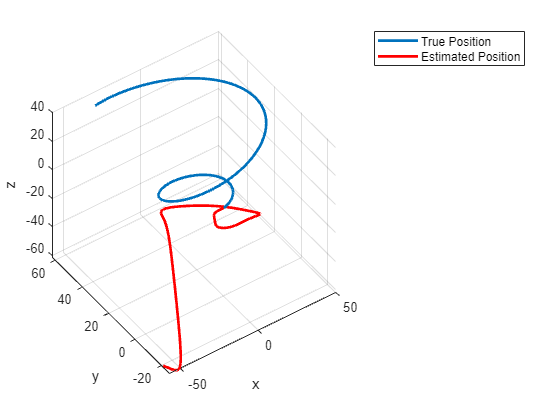


% Plot der geschätzten Position in 3D-Raum
figure(1);
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot3(estimated_position(1, :), estimated_position(2, :), estimated_position(3, :), 'r', 'LineWidth', 2);
hold off;
xlabel('x');
ylabel('y');
zlabel('z');
grid on;
legend('True Position', 'Estimated Position');

% Funktion zur Berechnung der Beobachtungen (Messmodell)

function obs = calculate_observations(x_k, pos_radar)
    obs = [sqrt((x_k(1) - pos_radar(1))^2 + (x_k(2) - pos_radar(2))^2 + (x_k(3) - pos_radar(3))^2);
           atan2(x_k(2) - pos_radar(2), x_k(1) - pos_radar(1));
           acos((x_k(3) - pos_radar(3)) / norm(x_k(1:3) - pos_radar))];
end


function H = create_observation_matrix(x_k, pos_radar1, pos_radar2)
    H = zeros(6, 6);
    H(1:3, 1:3) = eye(3);
    H(4:6, 4:6) = eye(3);
    
    obs_radar1 = calculate_observations(x_k, pos_radar1);
    obs_radar2 = calculate_observations(x_k, pos_radar2);
    
    % Beobachtung 1 (Abstand zu pos_radar1)
    dxyz = x_k(1:3, 1)' - pos_radar1;
    H(1, 1:3) = dxyz / obs_radar1(1);
    
    % Beobachtung 2 (Azimutwinkel zu pos_radar1)
    dxy = dxyz(1:2);
    H(2, 1:2) = [-dxy(2), dxy(1)] / norm(dxy)^2;
    
    % Beobachtung 3 (Elevationswinkel zu pos_radar1)
    H(3, 1:3) = [-dxy(1)*dxyz(3), -dxy(2)*dxyz(3), norm(dxy)^2] / (obs_radar1(3) * norm(dxyz)^3);
    
    % Beobachtung 4 (Abstand zu pos_radar2)
    dxyz = x_k(1:3, 1)' - pos_radar2;
    H(4, 1:3) = dxyz / obs_radar2(1);
    
    % Beobachtung 5 (Azimutwinkel zu pos_radar2)
    dxy = dxyz(1:2);
    H(5, 1:2) = [-dxy(2), dxy(1)] / norm(dxy)^2;
    
    % Beobachtung 6 (Elevationswinkel zu pos_radar2)
    H(6, 1:3) = [-dxy(1)*dxyz(3), -dxy(2)*dxyz(3), norm(dxy)^2] / (obs_radar2(3) * norm(dxyz)^3);
end

